# Dart Problem

# 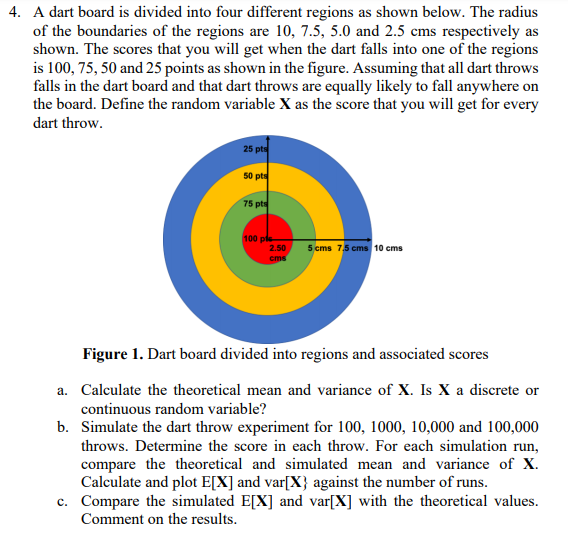

## Solution:

clc;clear all;close all;
%Here we are considering variable X as Score
dartRadius=10; % but since it is divided in 0.5 division we need 0.5 step means
dart=1:1:20;                  %20 division for 0.5 steps
score(dart>=0&dart<=2.5*2)=100;   %100pts
score(dart>2.5*2&dart<=5*2)=75;     %75pts
score(dart>5*2&dart<=7.5*2)=50;     %50pts
score(dart>7.5*2&dart<=10*2)=25;    %25pts
%Part A--------------------------------
%X is a discrete random variable of value 100,75,50,25
mean=sum(score)/length(score);
variance=(sum((score-mean).^2))/(length(score)-1);
fprintf('Part A->\n');

Part A->


fprintf('\tThe Mean is =%f\n',mean);

	The Mean is =62.500000


fprintf('\tThe Variance is =%f\n',variance);

	The Variance is =822.368421


%Part B--------------------------------
fprintf('Part B->\n');

Part B->


figure
%Dart through for 100
Darts100=zeros(1,100);
for i=1:100
    Darts100(1,i)=score(1,dart(1,ceil(20*rand(1,1))));
end
subplot 221
stem(1:100,Darts100);
title('100DartSimulation');
meanOf100=sum(Darts100)/length(Darts100);
varianceOf100=(sum((Darts100-meanOf100).^2))/(length(Darts100)-1);
fprintf('\tFor 100 Darts\n');

	For 100 Darts


fprintf('\t\tThe Mean is =%f\n',mean);

		The Mean is =62.500000


fprintf('\t\tThe Variance is =%f\n',varianceOf100);

		The Variance is =864.330808


%Dart through for 1000
Darts1000=zeros(1,1000);
for i=1:1000
    Darts1000(1,i)=score(1,dart(1,ceil(20*rand(1,1))));
end
subplot 222
stem(1:1000,Darts1000);
title('1000DartSimulation');
meanOf1000=sum(Darts1000)/length(Darts1000);
varianceOf1000=(sum((Darts1000-meanOf1000).^2))/(length(Darts1000)-1);
fprintf('\tFor 1000 Darts\n');

	For 1000 Darts


fprintf('\t\tThe Mean is =%f\n',meanOf1000);

		The Mean is =63.475000


fprintf('\t\tThe Variance is =%f\n',varianceOf1000);

		The Variance is =773.572948


%Dart through for 10000
Darts10000=zeros(1,10000);
for i=1:10000
    Darts10000(1,i)=score(1,dart(1,ceil(20*rand(1,1))));
end
subplot 223
stem(1:10000,Darts10000);
title('10000DartSimulation');
meanOf10000=sum(Darts10000)/length(Darts10000);
varianceOf10000=(sum((Darts10000-meanOf1000).^2))/(length(Darts10000)-1);
fprintf('\tFor 10000 Darts\n');

	For 10000 Darts


fprintf('\t\tThe Mean is =%f\n',meanOf10000);

		The Mean is =62.407500


fprintf('\t\tThe Variance is =%f\n',varianceOf10000);

		The Variance is =786.084608


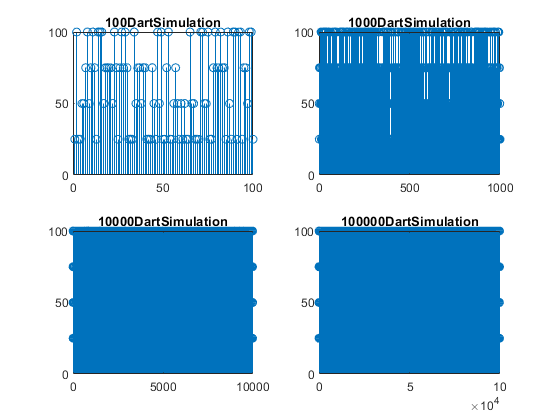

%Dart through for 100000
Darts100000=zeros(1,100000);
for i=1:100000
    Darts100000(1,i)=score(1,dart(1,ceil(20*rand(1,1))));
end
subplot 224
stem(1:100000,Darts100000);
title('100000DartSimulation');

meanOf100000=sum(Darts100000)/length(Darts100000);
varianceOf100000=(sum((Darts100000-meanOf1000).^2))/(length(Darts100000)-1);
fprintf('\tFor 100000 Darts\n');

	For 100000 Darts


fprintf('\t\tThe Mean is =%f\n',meanOf100000);

		The Mean is =62.596250


fprintf('\t\tThe Variance is =%f\n',varianceOf100000);

		The Variance is =785.308291


%Part C--------------------------------
fprintf('Part C->\n');

Part C->


fprintf('\t For 100 Dart Comparison From theoretical is:\n');

	 For 100 Dart Comparison From theoretical is:


fprintf('\t\tE[X]=%f,var[X]=%f,\n',mean-meanOf100,variance-varianceOf100);

		E[X]=0.750000,var[X]=-41.962387,


fprintf('\t For 1000 Dart Comparison From theoretical is:\n');

	 For 1000 Dart Comparison From theoretical is:


fprintf('\t\tE[X]=%f,var[X]=%f,\n',mean-meanOf1000,variance-varianceOf1000);

		E[X]=-0.975000,var[X]=48.795473,


fprintf('\t For 10000 Dart Comparison From theoretical is:\n');

	 For 10000 Dart Comparison From theoretical is:


fprintf('\t\tE[X]=%f,var[X]=%f,\n',mean-meanOf10000,variance-varianceOf10000);

		E[X]=0.092500,var[X]=36.283813,


fprintf('\t For 100000 Dart Comparison From theoretical is:\n');

	 For 100000 Dart Comparison From theoretical is:


fprintf('\t\tE[X]=%f,var[X]=%f,\n',mean-meanOf100000,variance-varianceOf100000);

		E[X]=-0.096250,var[X]=37.060130,


fprintf('\tHere we start seeing that more dart we through more closer we get to theoretical values\n')

	Here we start seeing that more dart we through more closer we get to theoretical values
